#  **3D image processing** **using 3D-DCT/DST**

This example shows how to process an colour image using the three-dimensional discrete cosine/sine transferm (3D DCT/DST).

Read an image into the workspace, then convert the image to double (after that,  convert it  to Single-precision floating).



[X,map] = imread('corn.tif');
if ~isempty(map)
    Im = ind2rgb(X,map);
end


Perform a 3D DCT of the colour image using the `Discrete_Transform_3D` function. Working only with Single-precision

J = Discrete_Transform_3D(Im, 'cosine', 'direct', 'one', 'row');
f = Discrete_Transform_3D(J, 'cosine', 'direct', 'two', 'column');

Reconstruct the image using the inverse 3D DCT function `Discrete_Transform_3D`.

K = Discrete_Transform_3D(f, 'cosine', 'inverse', 'two', 'column');
K = Discrete_Transform_3D(K, 'cosine', 'inverse', 'one', 'row');

Perform a full 3D DST of the colour image using the `Discrete_Transform_3D` function, and reconstruct the image using the inverse full 3D DST function Discrete_Transform_3D.

full = Discrete_Transform_3D(single(Im), 'sine', 'direct', 'four', 'full');
back = Discrete_Transform_3D(full, 'sine', 'inverse', 'four', 'full');

Display the original colour image alongside the processed image.

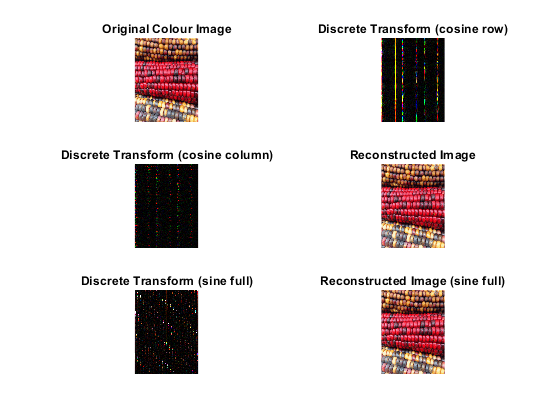

figure;
subplot(3,2,1),imshow(Im);
title('Original Colour Image');
subplot(3,2,2),imshow(J);
title('Discrete Transform (cosine row)');
subplot(3,2,3),imshow(f);
title('Discrete Transform (cosine column)');
subplot(3,2,4),imshow(K);
title('Reconstructed Image');
subplot(3,2,5),imshow(full);
title('Discrete Transform (sine full)');
subplot(3,2,6),imshow(back);
title('Reconstructed Image (sine full)');

figure

imshowpair(Im,K,'montage')

title('Original Colour Image (Left) and Reconstructed Image (Right)');